clc; clear all;

In the lecture we discussed this as an Moving Average Filter.


$$\longrightarrow H(z)= \frac{Y(z)}{X(z)}=\frac{1}{N}\sum_{k=0}^{N-1} z^{-k}=\frac{1}{N}\sum_{k=0}^{N-1} (1/z)^k$$


Due to the Geometrical row, we can write:


$$\sum_{k=0}^{N-1} a^{k}=\frac{1-a^N}{1-a}$$



$$\longrightarrow H(z)= \frac{1}{N}\sum_{k=0}^{N-1} (1/z)^k=\frac{1}{N}\frac{1-z^{-N}}{1-z^{-1}}$$


The System given in the Lab excersise is:


$$y\left(n\right)=y\left(n-1\right)+\frac{1}{N}\left(x\left(n\right)-x\left(n-1\right)\right)$$



$$\begin{array}{l}
Y\left(z\right)=Y\left(z\right)*z^{-1} +\left(1-z^{-1} \right)*X\left(z\right)*\frac{1}{N}\\
Y\left(z\right)-Y\left(z\right)*z^{-1} =+\left(1-z^{-1} \right)*X\left(z\right)*\frac{1}{N}
\end{array}$$


By applying the condition $H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}$, we receive:


$$H\left(z\right)=\frac{1-z^{-N} }{1-z^{-1} }*\frac{1}{N}$$


**The filter refers to an Moving Average Filter. The type of memory which is suitable for implementing the delay line is an FIFO.**

To show the behaviour of the filter, two pairs of b and a coefficients are created. One pair is created similar to the lecture using $H\left(z\right)=\frac{1-z^{-N} }{1-z^{-1} }*\frac{1}{N}$:

fs = 8000;         
Ts = 1/fs;         

N     = 4;

num   = [1 zeros(1,N-1) -1];    % Coefficients of the numerator polynomial (numerator) 
denom = [1 -1]*N;

The others refer to the equation $\longrightarrow H(z)= \frac{Y(z)}{X(z)}=\frac{1}{N}\sum_{k=0}^{N-1} z^{-k}=\frac{1}{N}\sum_{k=0}^{N-1} (1/z)^k$

b = [0.25 0.25 0.25 0.25];
a = [1];

The Input Signal is generated like in the Lecture:

T = 1;
M = T/Ts;
n = 0:1:M-1; 

f1 = 100; 

P1 = 2*round(fs/f1);

x1 = sin(2*pi*f1*Ts*n); 

After that the filter command is used to execute the filter operation.

y_num_denom = filter(num,denom,x1);
y_b_a = filter(b,a,x1);

Plot $H\left(z\right)=\frac{1-z^{-N} }{1-z^{-1} }*\frac{1}{N}$

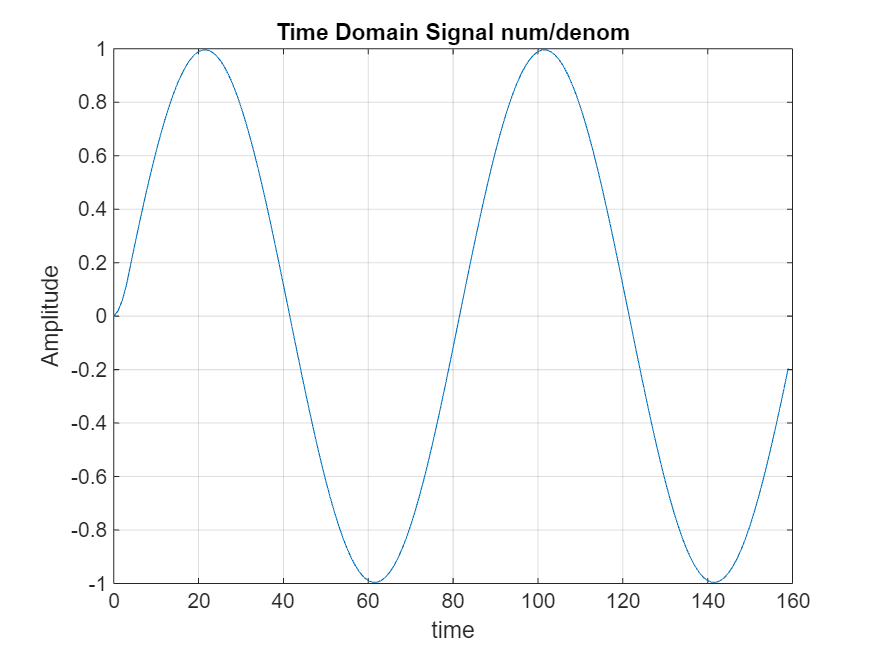

figure()
plot(n(1:P1),y_num_denom(1:P1));
title('Time Domain Signal num/denom');
xlabel('time');
ylabel('Amplitude');
grid on;

Plot $\longrightarrow H(z)= \frac{Y(z)}{X(z)}=\frac{1}{N}\sum_{k=0}^{N-1} z^{-k}=\frac{1}{N}\sum_{k=0}^{N-1} (1/z)^k$

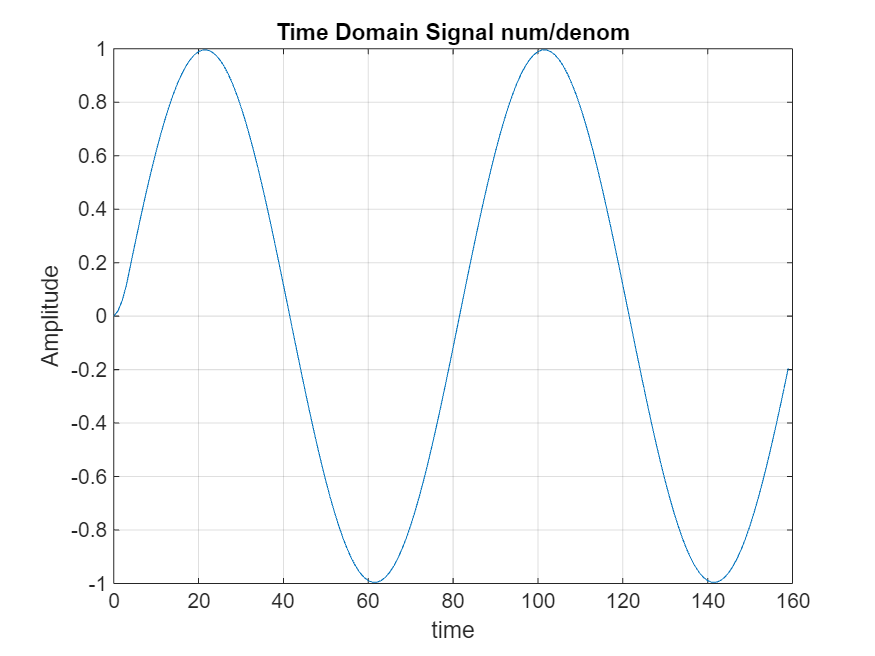

figure()
plot(n(1:P1),y_b_a(1:P1));
title('Time Domain Signal num/denom');
xlabel('time');
ylabel('Amplitude');
grid on;